# `Numerical Derivatives Group Assignment`

#### `Bethany Wu & Alex Stapely`

## `Problem 1: Finite Differences`

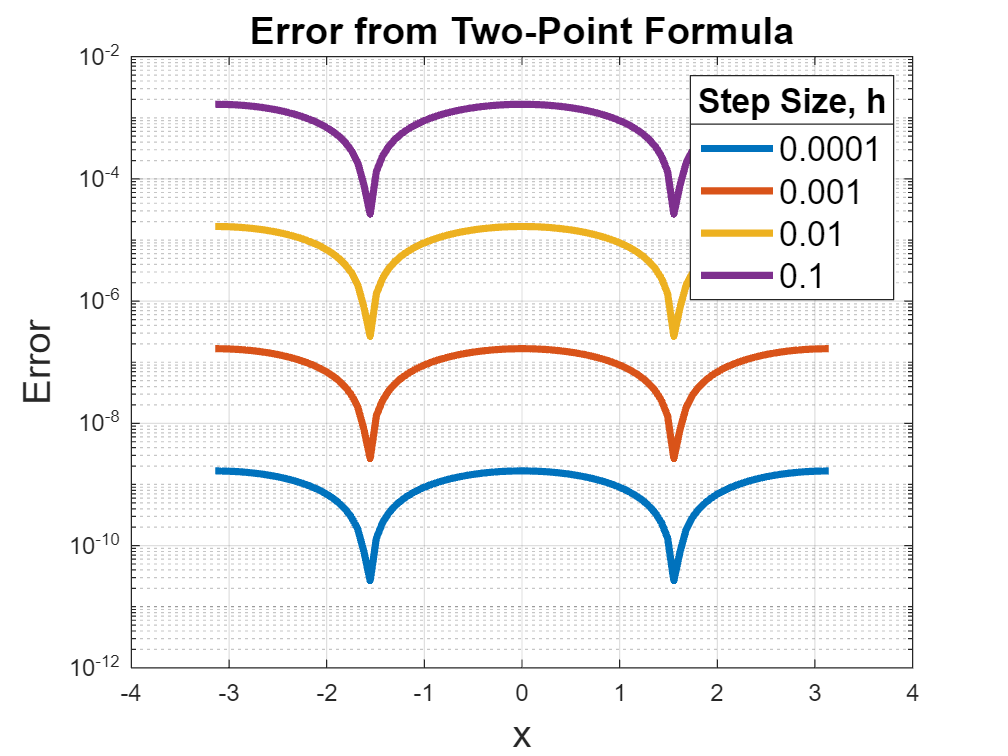

syms x0 h0
x = linspace(-pi,pi,100);
y = @sin;
dydx = @(x0,h0)  (y(x0+h0)-y(x0-h0))/(2*h0);

hs = [0.0001 0.001 0.01 0.1];
figure();
for h = hs
    yp = dydx(x,h);
    semilogy(x,abs(yp-cos(x)),'LineWidth',3); hold on;
end
title('Error from Two-Point Formula','FontSize',16); xlabel('x','FontSize',16); ylabel('Error','FontSize',16);
leg = legend(string(hs),'FontSize',14); title(leg,'Step Size, h'); grid on; hold off;

`Looking at the error plot, as h is decreased by an order of magnitude, the overall error of the derivative using the two-point formula us decreased by TWO orders of magnitude! When h = 1e-4, the error is in the range 1e-11 to 1e-9.`

## `Problem 2: More sophisticated derivatives...`

### `Part (a)`

`Richardson extrapolation of the finite difference formulas: Alex`

%Example use of Richardson extrapolation
f=@(x) sin(x);
% x = Point(s) to evaluate at
x = pi;
% Step
h = 0.4;
% Order of extrapolation 
n = 4;
der = richardson(f,x,h,n);
% Prints Result
fprintf('According to the Richardson extrapolation method, the derivative is: %.9f\n', der);

According to the Richardson extrapolation method, the derivative is: -0.999999998


`Chebyshev methods: Bethany`

## `Part (b)`

% %Write a driver function that allows you to use a common interface to apply the methods 
% % you implemented in part (a) with an arbitrary function. 
% 
% % Set up arbitrary function and parameters
% f=@(x) sin(x);
% % x = Point(s) to evaluate at
% x = pi;
% % Step
% h = 0.4;
% % Order of extrapolation 
% n = 4;

% % Calling that function here
% compare(f,x,h,n)

## `Part (c)`

% sin(x) for 100 points between -pi and pi
f=@(x) sin(x);
xs = linspace(-pi,pi,100);
h = 0.4;
n = 4;
compare(f,xs,h,n)

RMSE of the Richardson method with actual derivative: 0.67
Took 0.0154 seconds to compute.
RMSE of the Chebyshev method with actual derivative: 0.67
Took 0.2601 seconds to compute.


% sin(1/x) for 100 points between [-1,1]
f2=@(x) 1./sin(x);
xs2 = linspace(-1,1,100);
compare(f2,xs2,h,n)

RMSE of the Richardson method with actual derivative: 12094.39
Took 0.0032 seconds to compute.
RMSE of the Chebyshev method with actual derivative: 2785.80
Took 0.4487 seconds to compute.


% 3x^2 + 1/(pi^2)*ln((pi-x)^2)+1 for 100 points between [3.14,3.16]
f3=@(x) 3*x.^2 + 1./(pi.^2).*log((pi-x).^2)+1;
xs3 = linspace(3.14,3.16,100);
compare(f3,xs3,h,n)

RMSE of the Richardson method with actual derivative: 44.99
Took 0.0090 seconds to compute.
RMSE of the Chebyshev method with actual derivative: 262.75
Took 0.3992 seconds to compute.


## `Part (d)`

# `Functions`

function der  = richardson(f, x, h, n)
    R(1,1) = (f(x+h)-f(x))/h;
    for i = 1:n
        h = h/2;
        R(i+1,1)=(f(x+h)-f(x))/h;
        for j=1:i
            R(i+1,j+1)=(2^j*R(i+1,j)-R(i,j))/(2^j-1);
        end
    der = R(i+1,j+1);
    end
end

function deriv = chebyshev_diff(func,a,b,numPts)
    % Uses open-source package, Chebfun!
    cf = chebfun(func,linspace(a,b,numPts));
    df = diff(cf);
    deriv = df.pointValues';
end

% This function is written for part b. Used to compare the different methods
% from part a 
function compare(arbitrary_function,xs,h,n)
    % Richardson Method
    der_rich=zeros(1,100); tic;
    for i = 1:100
        x = xs(i);
        der = richardson(arbitrary_function, x, h, n);
        % Put next function here 
        %fprintf('According to the Richardson extrapolation method, the derivative is: %.4f\n', der);
        % fprintf('According to the other method, the derivative is: %.9f\n', der);
        der_rich(i) = der;
    end
    t_rich = toc;

    % Chebyshev method
    tic;
    der_cheb = chebyshev_diff(arbitrary_function,xs(1),xs(end),length(xs));
    t_cheb = toc;
    
    % Compute actual derivative
    func_deriv = diff([arbitrary_function(xs) 0]);

    % Compare RMSE of each method with actual derivative
    fprintf("RMSE of the Richardson method with actual derivative: %.2f\nTook %.4f seconds to compute.\n" + ...
        "RMSE of the Chebyshev method with actual derivative: %.2f\nTook %.4f seconds to compute.\n",rmse(der_rich,func_deriv),t_rich,rmse(der_cheb,func_deriv),t_cheb);
    
end